# Supply Chain Network Simulator

clear all
close all
clc

netId = 1;               % Supply chain network ID
numOfChains = 3;         % Number of parallel chains
numOfInventories = 5;    % Each chain has 3 inventories

% Create Network
net = Network(netId, numOfChains, numOfInventories);

Started creating the supply chain network.
Started creating chain 1
Started creating a supply...
Finished creating a supply...
Started creating an inventory...
Finished creating an inventory...
Started creating an inventory...
Finished creating an inventory...
Started creating an inventory...
Finished creating an inventory...
Started creating an inventory...
Finished creating an inventory...
Started creating an inventory...
Finished creating an inventory...
Started creating a demand...
Finished creating a demand...
Started creating a PhyLink...
Finished creating a PhyLink...
Started creating a PhyLink...
Finished creating a PhyLink...
Started creating a PhyLink...
Finished creating a PhyLink...
Started creating a PhyLink...
Finished creating a PhyLink...
Started creating a PhyLink...
Finished creating a PhyLink...
Started creating a PhyLink...
Finished creating a PhyLink...
Finished creating a chain...
Started creating chain 2
Started creating a supply...
Finished creating a supply...


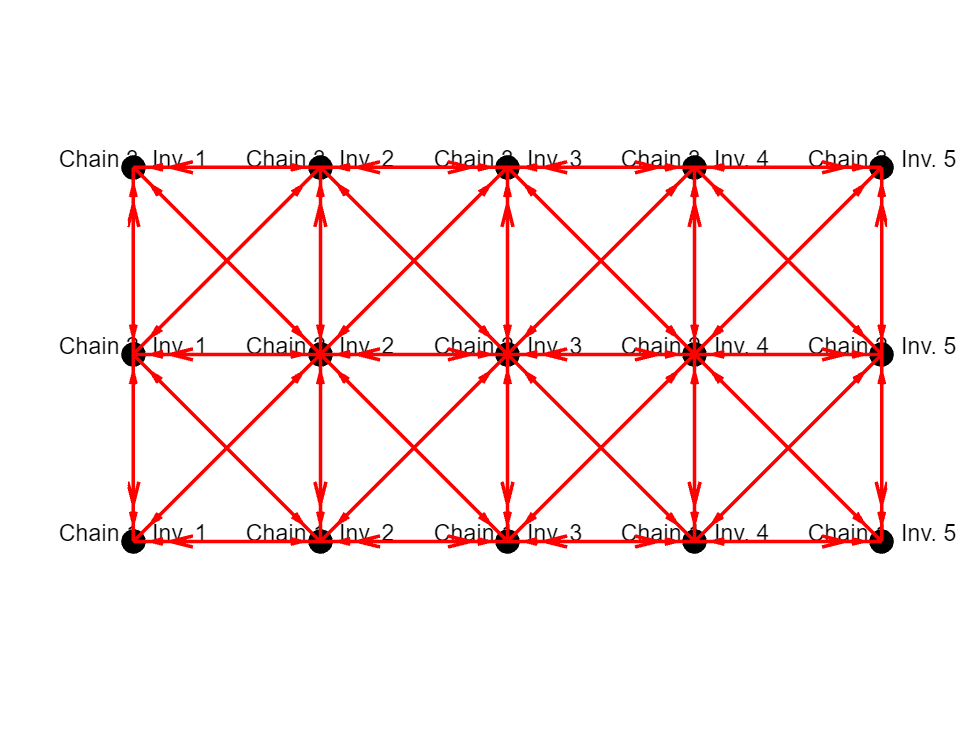


figNum = 1;
figure(figNum); hold on; axis equal; axis off;
net.plotConnections();

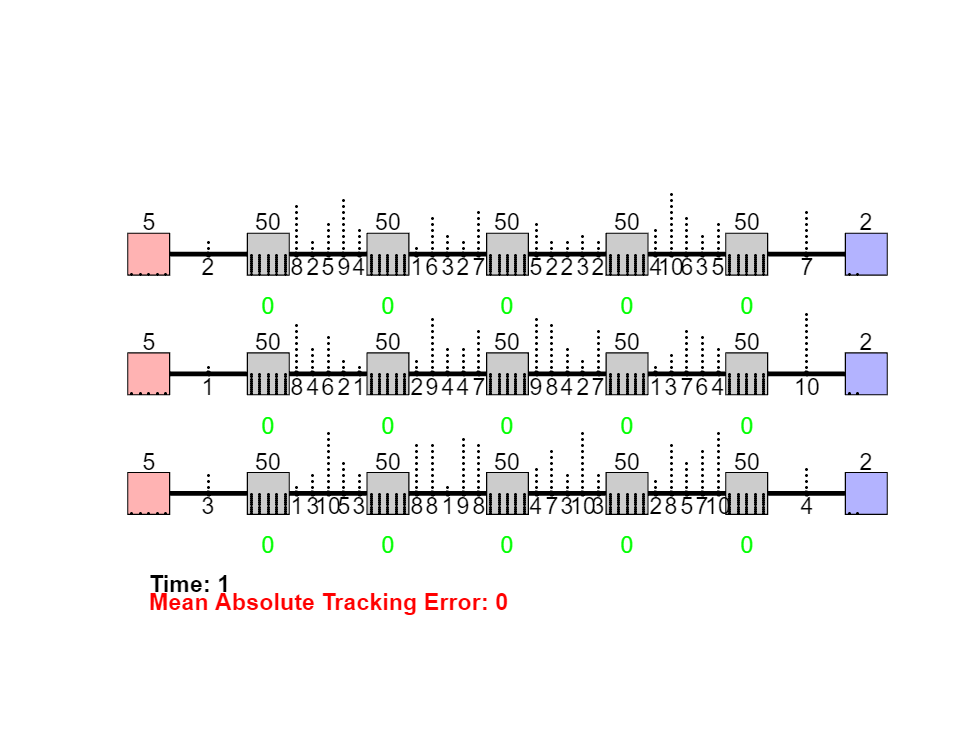


% Set up the figure 
figNum = figNum + 1;
figure(figNum);
hold on; axis equal; axis off;
net.draw(1); 

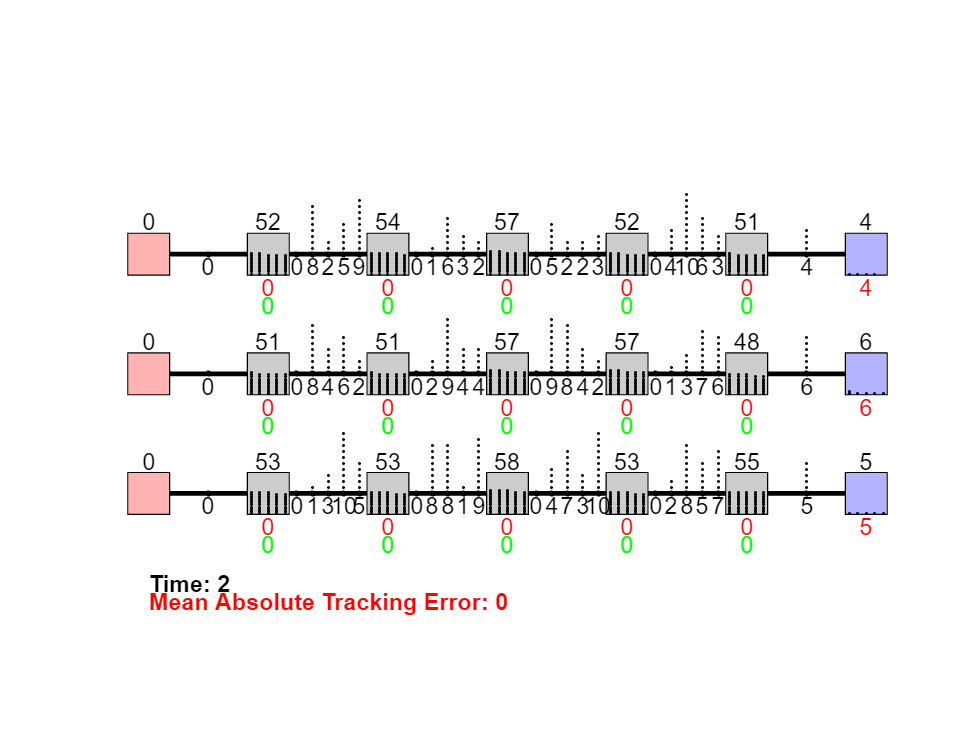

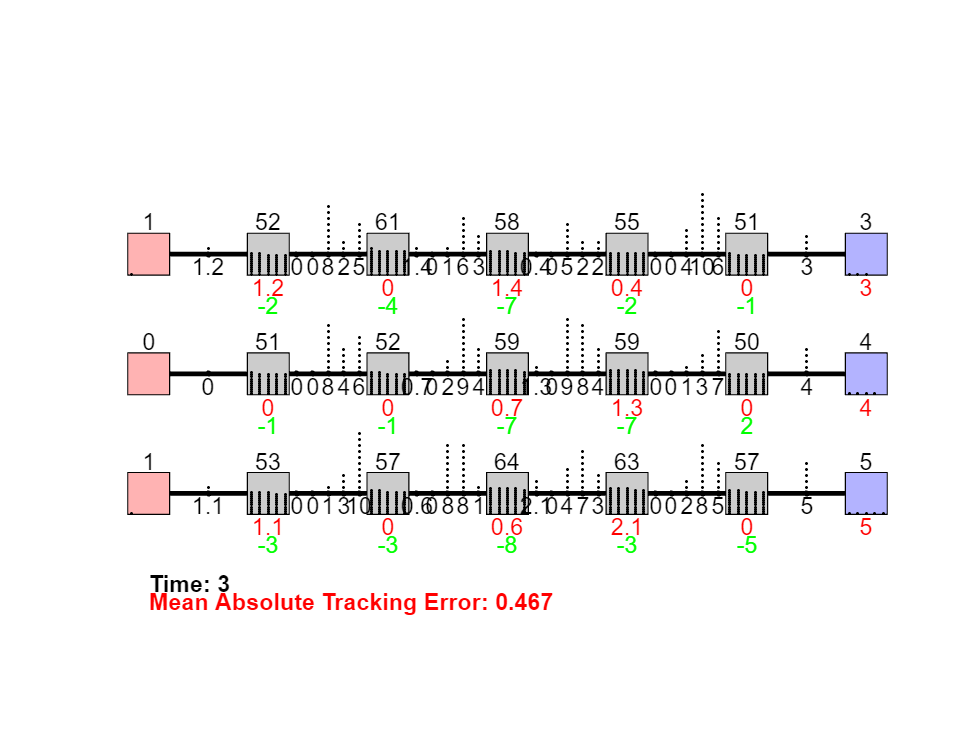

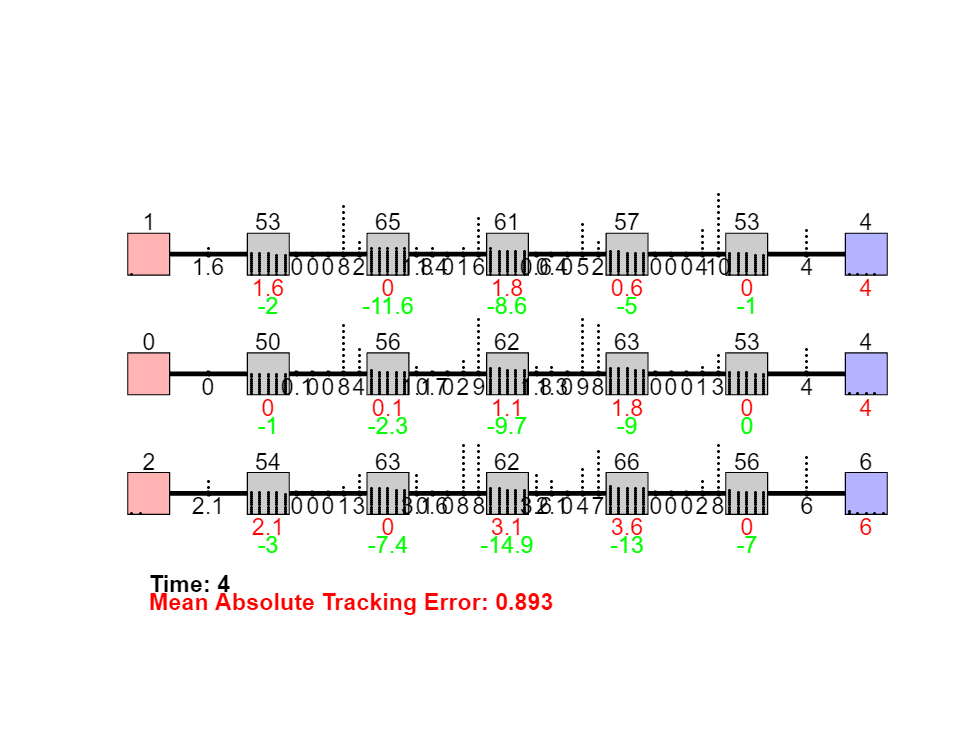

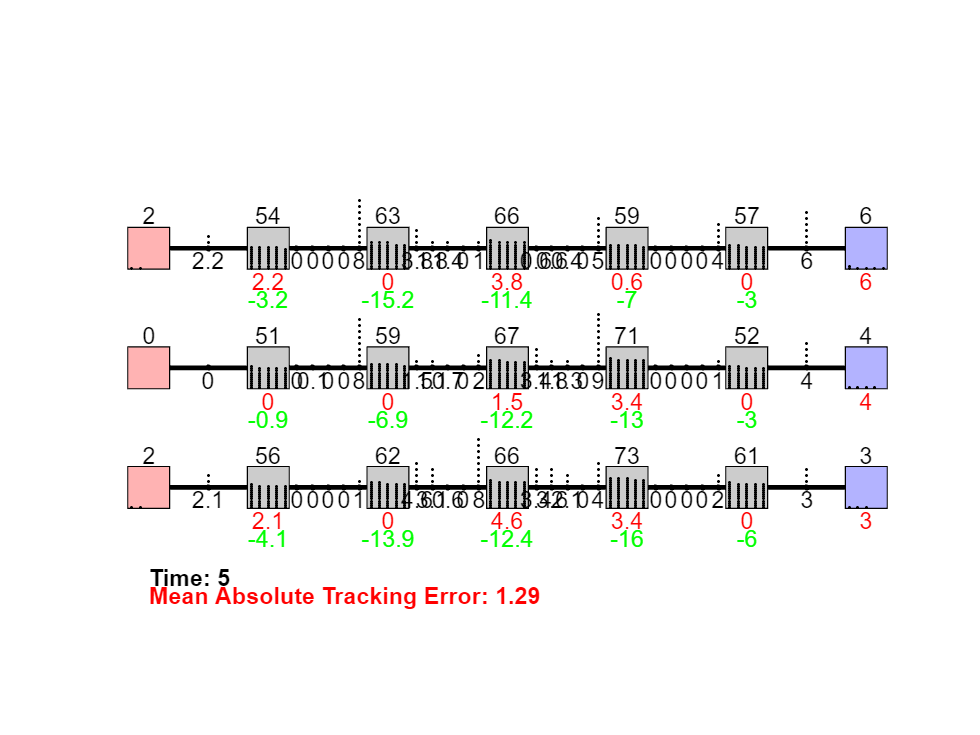

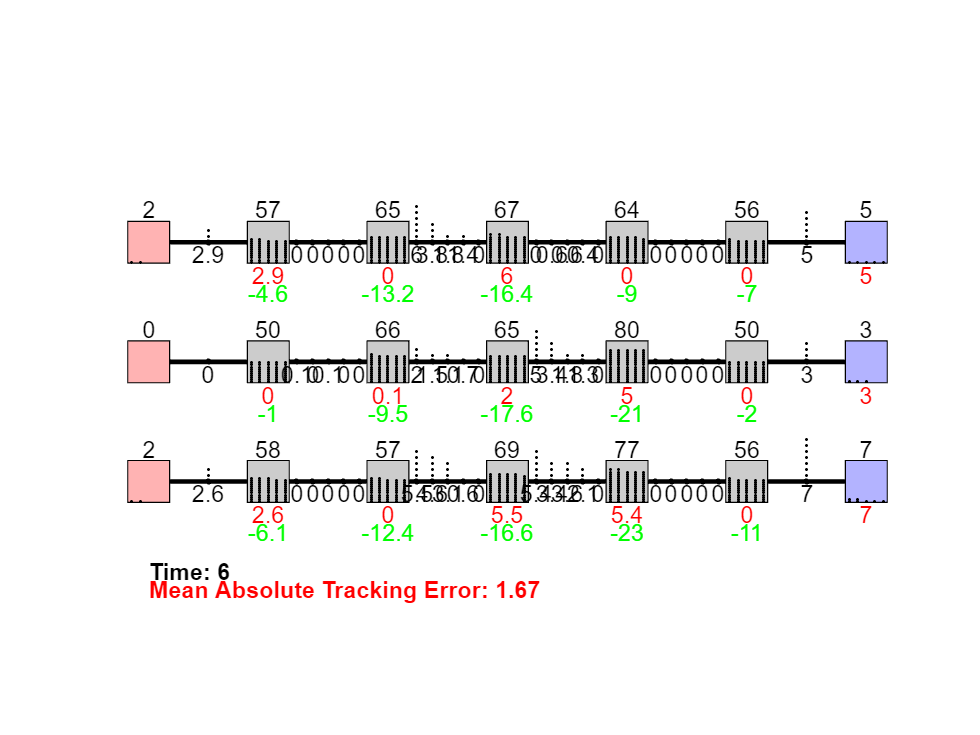

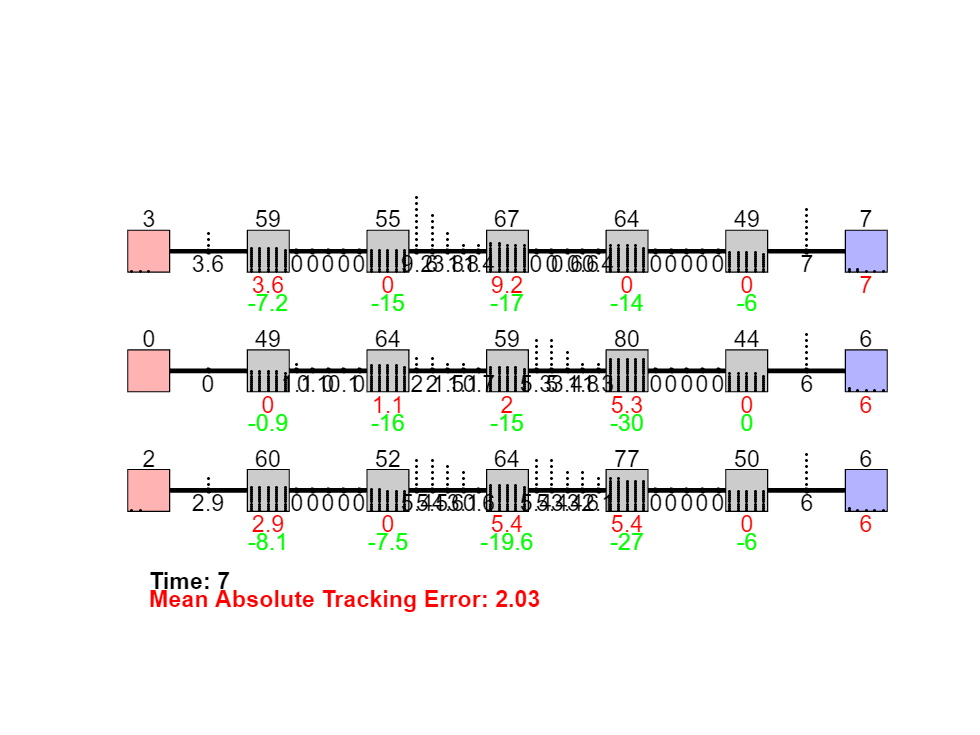

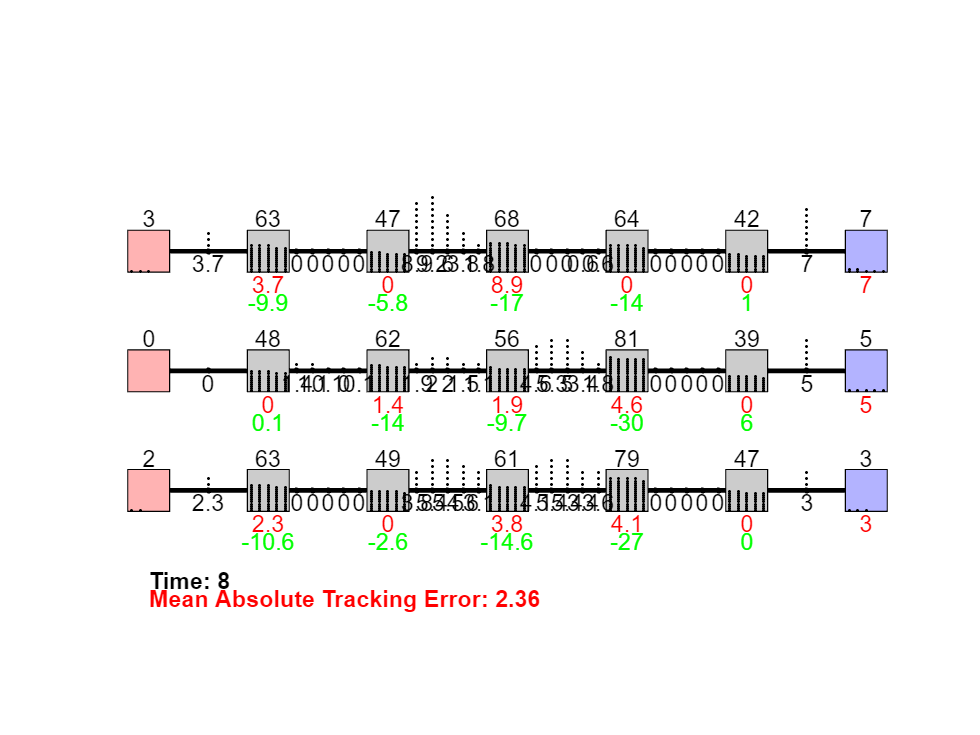

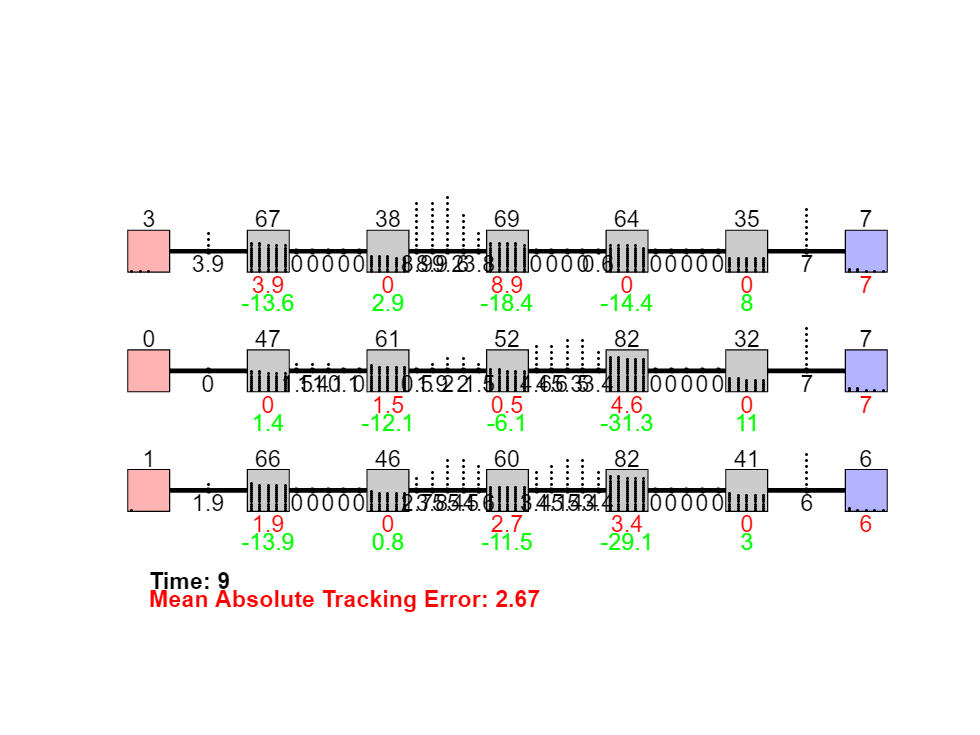


% Simulation loop
for t = 2:1:10
    net.update();  % Update the entire network

    figNum = figNum + 1;
    figure(figNum);
    hold on; axis equal; axis off;

    % % Clear the figure, then hold on to plot without erasing previous state
    % pause(0.1);  % Pause to visualize each step
    % clf; 
    % hold on; axis equal; axis off;
 
    
    % Draw the network state after each update with the current time
    net.draw(t);  % Pass the current time to the draw function
end

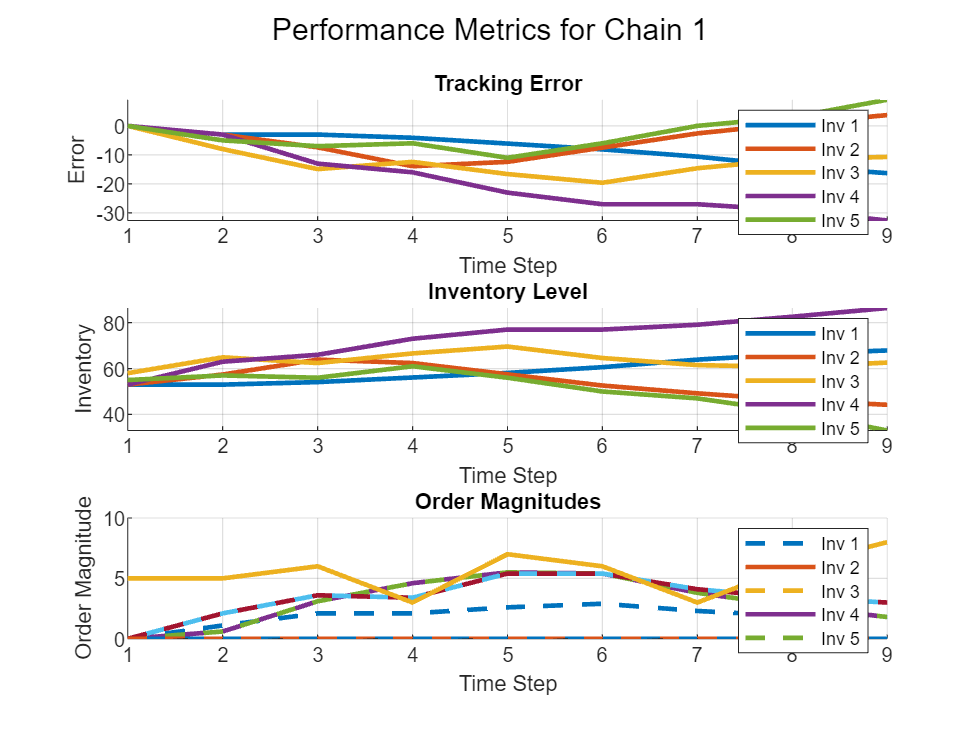

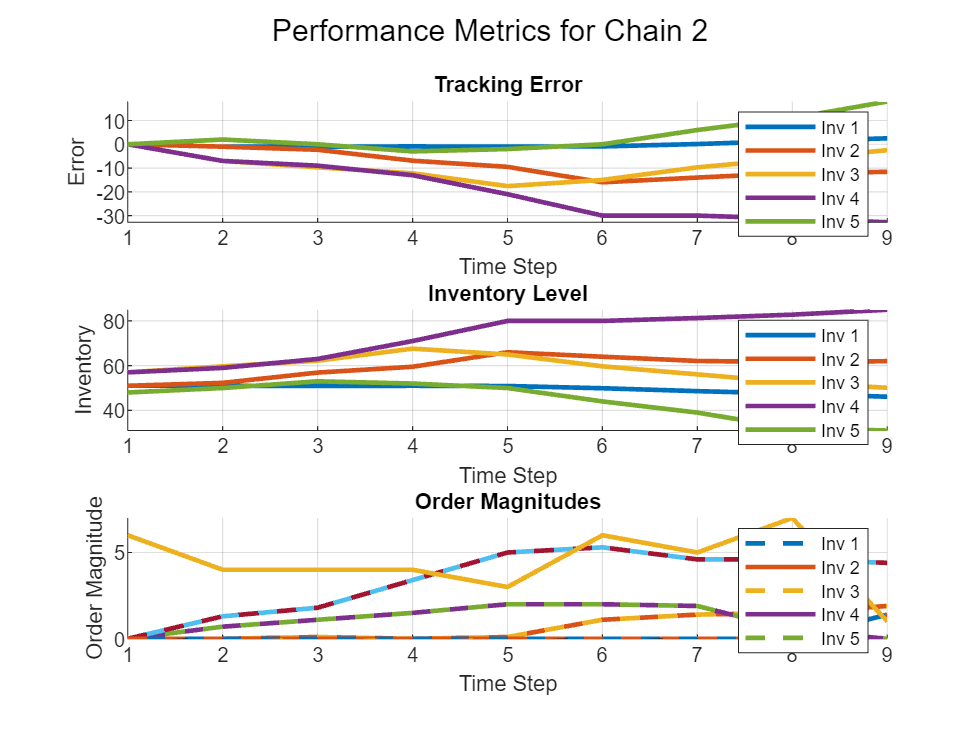

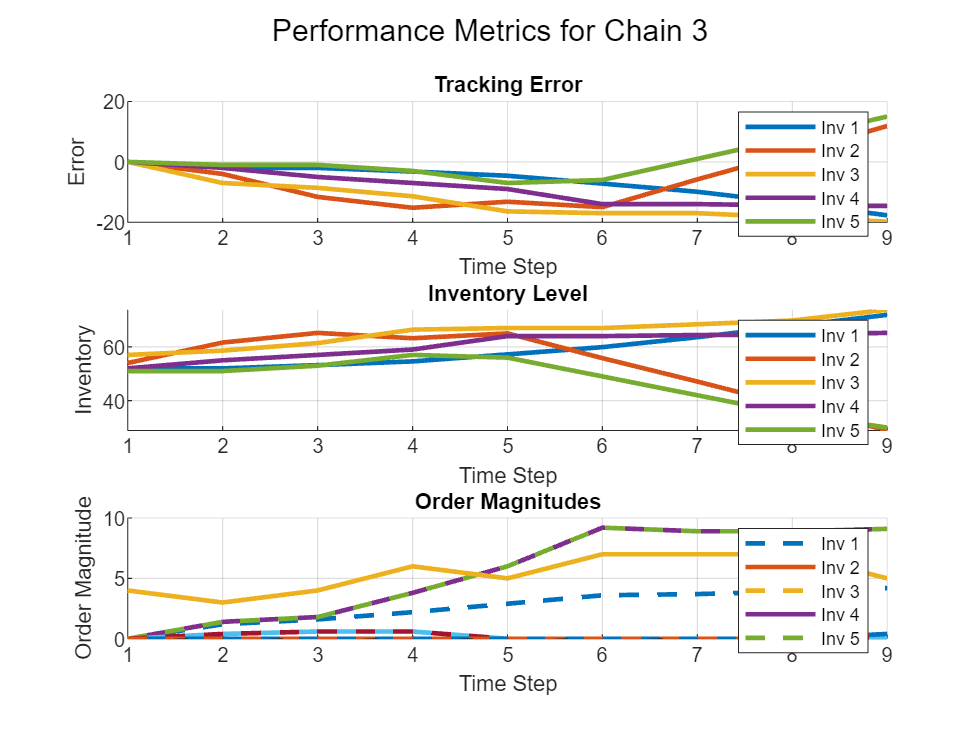


% After the simulation, generate performance plots
net.plotNetworkPerformance();